%analyze_series8.m



%start with clean slate (nobkpt)
clear       %no variables
close all   %no figures
clc         %empty command window

% Data Access
%----------------------------------------------------------------------

%filename convention used in image series (nobkpt)
prefix = 'D:\Data\2023_03_27_Suyash\2023_03_27_Suyash\2719_Flash_FA3\1\2719_';
fnum = 00001:00128;
ext = '.dcm';

%first filename in series (nobkpt)
fname = [prefix sprintf('%05d',fnum(1)) ext];

%examine file header (nobkpt)
info = dicominfo(fname)

info = struct with fields:
                          Filename: 'D:\Data\2023_03_27_Suyash\2023_03_27_Suyash\2719_Flash_FA3\1\2719_00001.dcm'
                       FileModDate: '30-Mar-2023 10:16:18'
                          FileSize: 67308
                            Format: 'DICOM'
                     FormatVersion: 3
                             Width: 128
                            Height: 256
                          BitDepth: 12
                         ColorType: 'grayscale'
    FileMetaInformationGroupLength: 204
        FileMetaInformationVersion: [2×1 uint8]
           MediaStorageSOPClassUID: '1.2.840.10008.5.1.4.1.1.4'
        MediaStorageSOPInstanceUID: '1.2.826.0.1.9717382.1092.22.1.1.134.2719.1.20230327154848.1'
                 TransferSyntaxUID: '1.2.840.10008.1.2.1'
            ImplementationClassUID: '1.2.276.0.7230010.3.0.3.6.4'
         ImplementationVersionName: 'OFFIS_DCMTK_364'
              SpecificCharacterSet: 'ISO_IR 100'
                         ImageTy


%extract size info from metadata (nobkpt)
voxel_size = [info.PixelSpacing; info.SliceThickness]'

voxel_size =     0.2734    0.2734    0.2700



%read slice images; populate XYZ matrix
hWaitBar = waitbar(0,'Reading DICOM files');
for i=length(fnum):-1:1
    fname = [prefix sprintf('%05d',fnum(i)) ext];
    D(:,:,i) = uint16(dicomread(fname));
    waitbar((length(fnum)-i)/length(fnum))
end
delete(hWaitBar)
whos D

  Name        Size                   Bytes  Class     Attributes

  D         256x128x128            8388608  uint16              



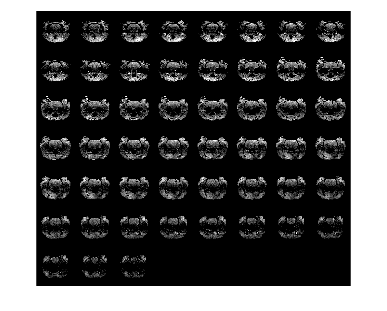


% Transform for axial view
D_axial = zeros(size(D,3),size(D,2),size(D,1));
for i = 1:size(D,1)
    new_axial = reshape(D(i,:,:),[size(D,2),size(D,3)]);
    D_axial_elem = flipdim(new_axial',1);
    D_axial(:,:,i) = D_axial_elem;
end

montage(D_axial(:,:,125:175),"DisplayRange",[600,1200])

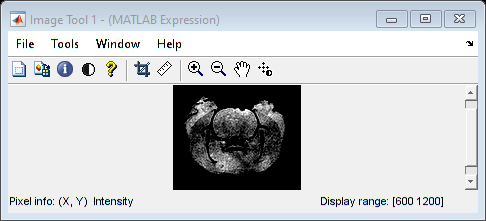

imtool(D_axial(:,:,155),"DisplayRange",[600,1200])

function threshold_image(img,lower_bound, upper_bound)
end